% % getting whole group workflow (up til now) together

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend 

% group matrix

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

cont = 1:length(uniqueContrasts)
%cont = 7;

% LOCO NO PUP - makes group matricies, need this for all other figs/analyses

% stat group CRF matrix
state = 'loRun'
clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)
% run group CRF matrix
state = 'hiRun'
clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 

% LO BEH STATE

% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:

[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts)

size_loRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts)

size_loRun_stdErrCRF_acrossSess_allPts =      5     7



% HI BEH STATE
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts)

size_hiRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts)

size_hiRun_stdErrCRF_acrossSess_allPts =      5     7


% we now have man CRF across sessions/mice for each visual area

% for 1 dur,
% 1 point, 
% one state

d = 1;
i = 1;

% take the ith CRF
ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);

% interpolate CRF (results will have flipped axes - con (interpolated part) on y, mean df per con (not interpolated, or also interpolated?) on x axis
% "interpolate contrast as a funciton of fluorescence response"
% "fnd x value for y = 50% max"

% interpoalate contrsntrast as funciton of respnse, fnd x value for y = 50% max
% interp1d(response, contrast, 1/2 max reponse) 

% note: for linear interpolation, In words, the error is proportional to the square of the distance between the data points.

% vq = interp1(x,v,xq) returns interpolated values of a 1-D function at specific query points using linear interpolation.
% r x contains the sample points, and v contains the corresponding values, v(x). 
% Vector xq contains the coordinates of the query points

x_samplePoints = 1:length(uniqueContrasts);
v_correspondingValues = ith_mnCRF_acrossSess_AllDurAllPts_lo;
xq = 

% find the range of df (max df - min df)
range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
% divide range by 2
halfOf_range = range/2;
% subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
yval_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;

xval_C50 = ?

% find con associated 1/2 max df/range value

% vq = interp1(v,xq) returns interpolated values and 
% assumes a default set of sample point coordinates. 
% The default points are the sequence of numbers from 1 to n, 
% where n depends on the shape of v:
% When v is a vector, the default points are 1:length(v).
% When v is an array, the default points are 1:size(v,1)
% Use this syntax when you are not concerned about the absolute distances between points (??)
% This syntax is not recommended. Use griddedInterpolant instead. (???)

% I think I want the interpolated contrast value, not interpolated df value 

%vq = interp1(x,v,xq)

y_conNeedInterp = x_samplePoints;
interpQueryPts = y_conNeedInterp; % NO!
%No - here's where I want to query whatever con is at 1/2 max... do I input a function of y or...?

interp1(y_conNeedInterp,ith_mnCRF_acrossSess_AllDurAllPts_lo,interpQueryPts)


% we now have man CRF across sessions/mice for each visual area

% for 1 dur,
d = 1;
% 1 point, 
i = 1;

% one state at a time

% take the ith CRF
ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);

% vq1 = interp1(x,v,xq);
% plot(x,v,'o',xq,vq1,':.');

% the output (y value) of interp1 is going to be an interpolated contrasts vector 
% the x value input to interp() is df ('ith_mnCRF_acrossSess_AllDurAllPts_lo')

% I have a function, y (mn df) vs x (contrast). I need finer respolution on contrast.
% interp function will use the df values as x axis and linear approximation to interpolate
% the corresponding contrasts (even if the df value is not interpolated too, I guess
% -that's kind of the point of interpolation, to find y values where there are no x *or* y values)
% interp outputs it's *own* y axis - that of the interpolated contrast values. 
% third variable into interp1() is for the resolution of the output (contrasts) of the function, 
% which is given in terms of the x input values to the finction (df's). 

% let's try doing it closer to the online example..

% x is df vector
x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;

% resolution of interpolation 
higherRes = 1/10; % to get 10 con points in between each of 7 df values
x_isDf_higherRes = 1:higherRes:length(x_is_df);

% the y input to inpterp() is the thing you want interpolated according to the resolution set above
y_is_cons = uniqueContrasts;


% interpolate contrast
interpedConsCurve = interp1(x_is_df,y_is_cons,x_isDf_higherRes);


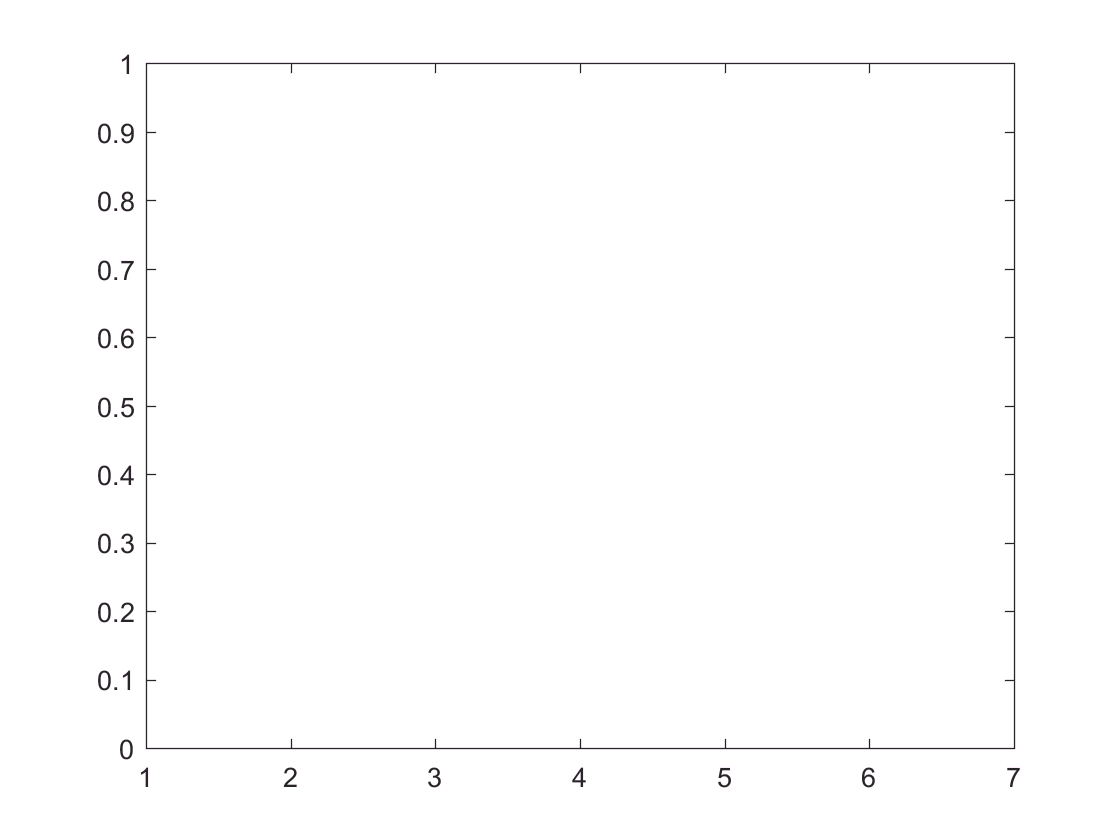

figure
% plot regular CRF curve with interpolated curve over it
%plot(uniqueContrasts,ith_mnCRF_acrossSess_AllDurAllPts_lo,'o',x_isDf_higherRes,interpedConsCurve,':.')
plot(x_isDf_higherRes,interpedConsCurve)
xlim([1 7])

% find C50 on interpolated curve

% find the range of df (max df - min df)
range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
% divide range by 2
halfOf_range = range/2;
% subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;

% need to find where df_at_50 index is for higher res indexing

% find indicies for all df's greater than C50 value
idx_ith_mnCRF_acrossSess_AllDurAllPts_aboveC50 = find(ith_mnCRF_acrossSess_AllDurAllPts_lo>df_at_C50);
% Find the index of the minimum df value over 50 
% index the df vector and the min df value will be df that's 1/2 max
hiRes_df_at_C50 = min(x_isDf_higherRes(idx_x_isDf_higherRes_aboveC50));

C50 = interpedConsCurve(hiRes_df_at_C50)


hold on 

plot(df_at_C50,C50,'*')


